## Loading in data

subjectNames = {
    'nstdb/118e24';
    'nstdb/118e18';
    'nstdb/118e12';
    'nstdb/118e06';
    'nstdb/118e00';
    'nstdb/118e_6';
    'nstdb/119e24';
    'nstdb/119e18';
    'nstdb/119e12';
    'nstdb/119e06';
    'nstdb/119e00';
    'nstdb/119e_6'
};
%set number of files
files = length(subjectNames);
%Initialize Arrays
Fs = zeros(files,1);
ecg = cell(files,1);
tm = cell(files,1);
rr = cell(files,1);
%loop through all file names
for fi = 1:files
    [ecg{fi,1},Fs(fi),tm{fi,1}]= rdsamp(subjectNames{fi,1},1);
    [rr{fi,1},tm{fi,1}]=ann2rr(subjectNames{fi,1},'atr');
end 
%Note: Noise was added beginning after the first 5 minutes of each record, during two-minute segments alternating with two-minute clean segments.

## Plotting Data

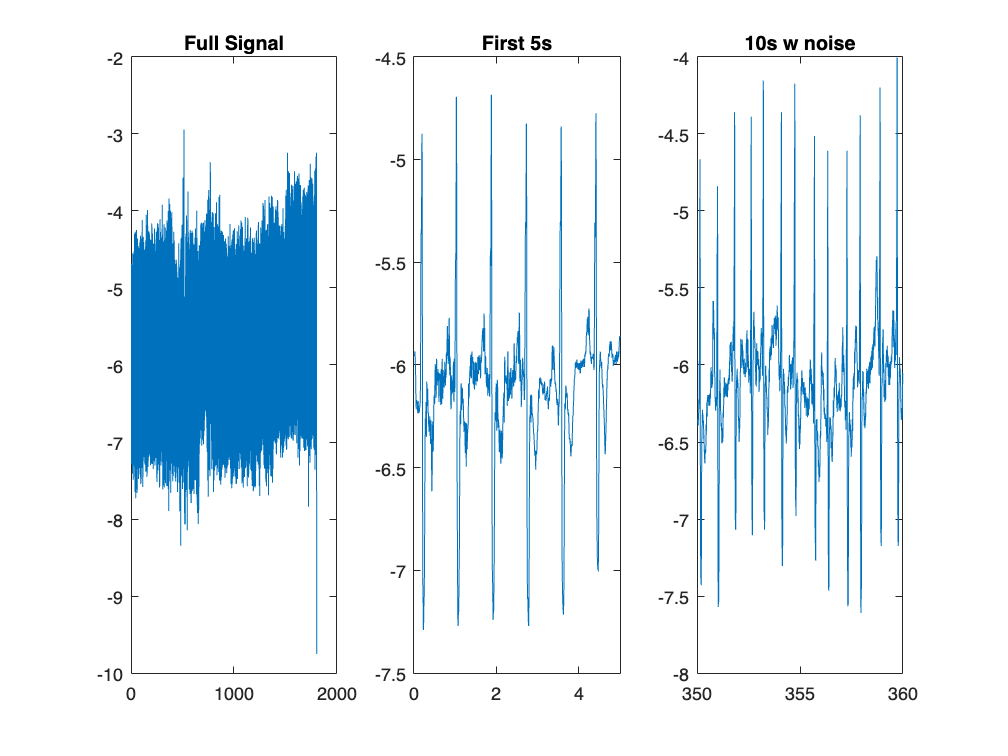

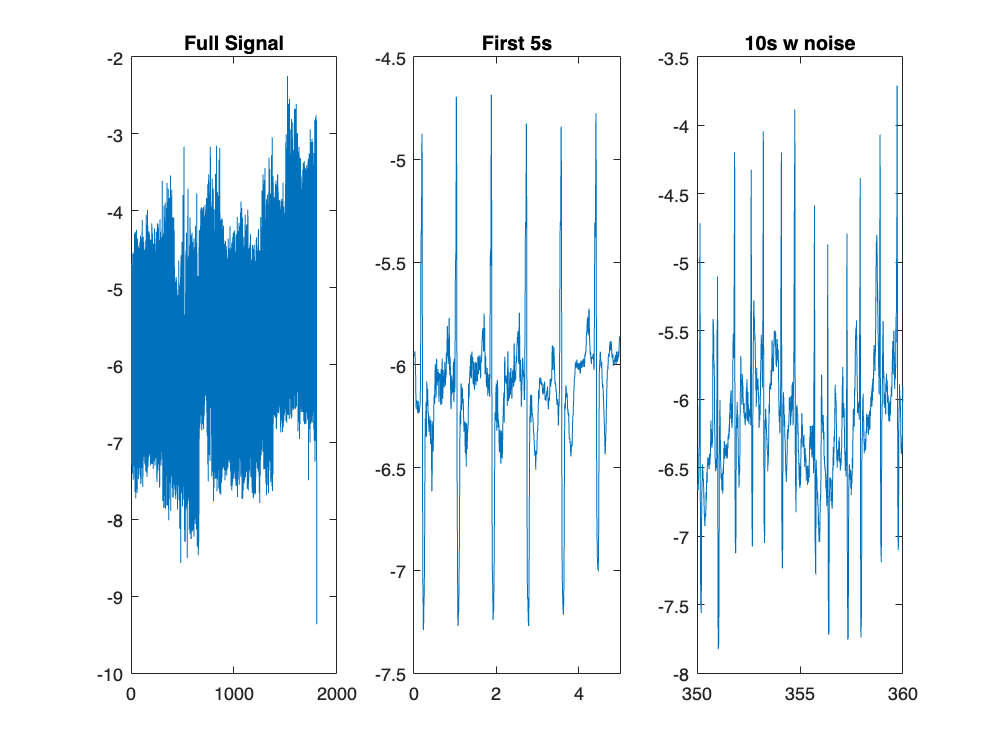

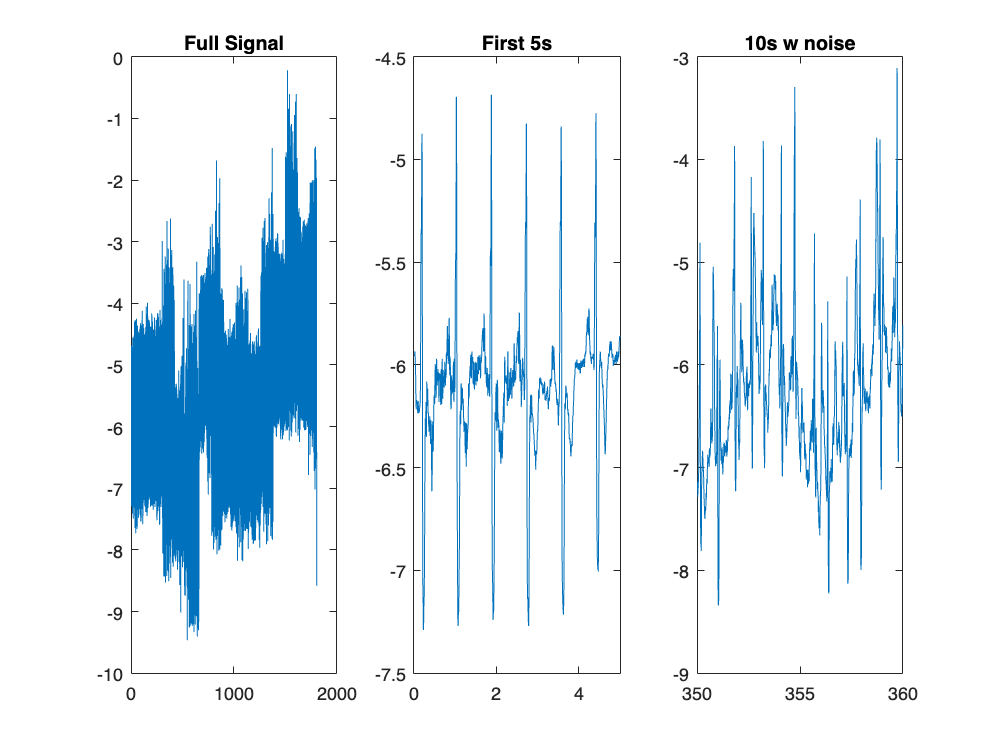

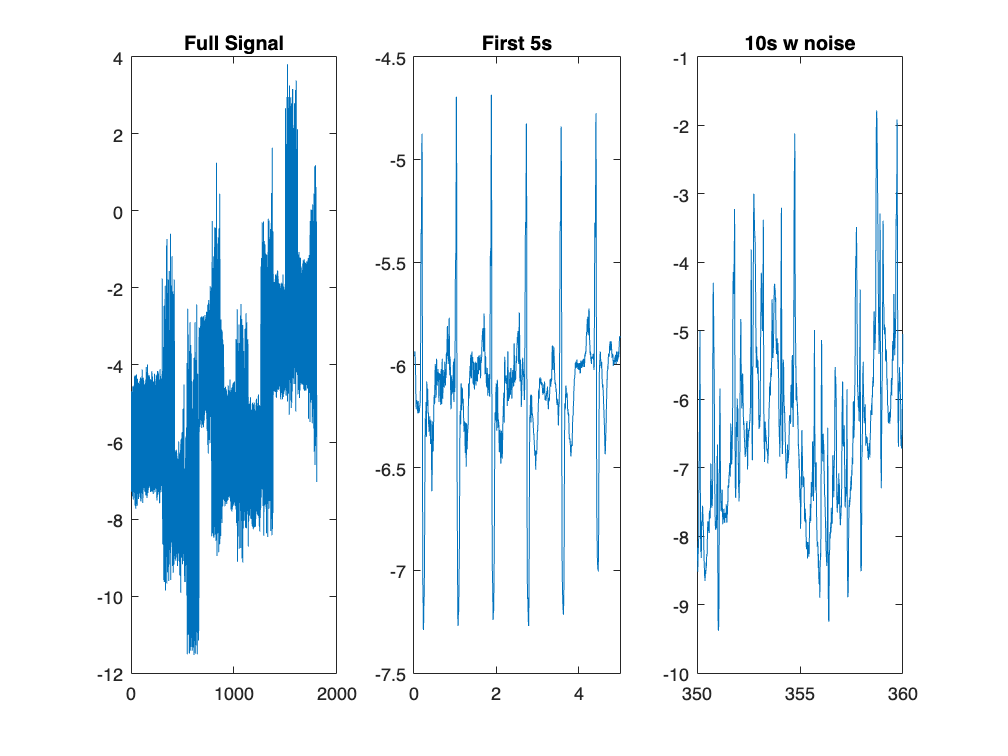

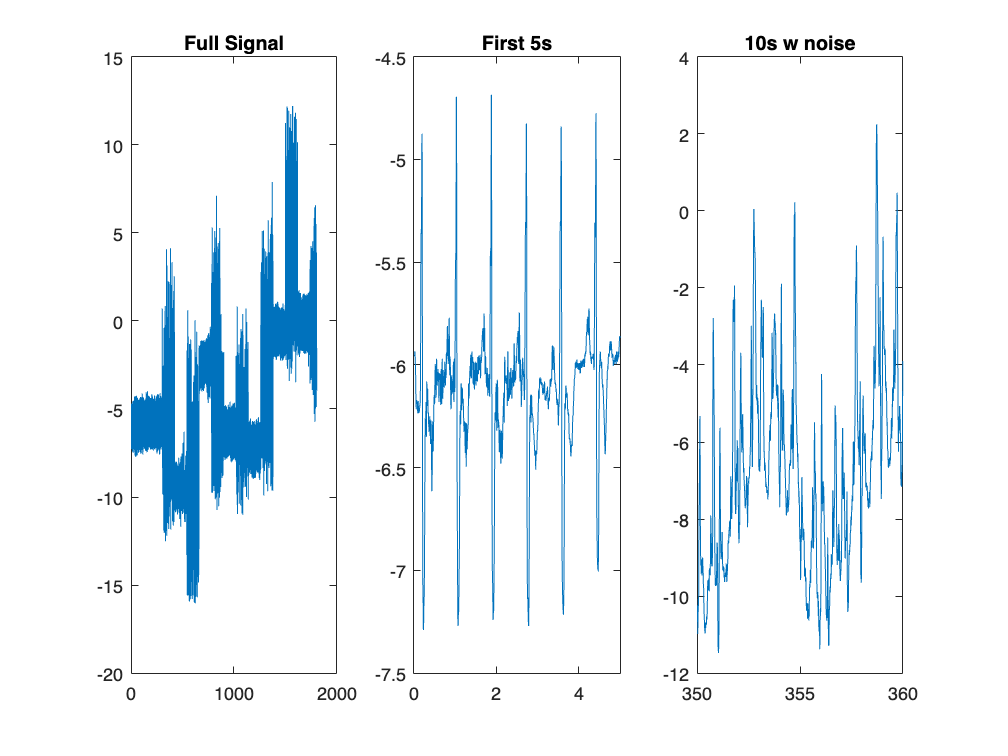

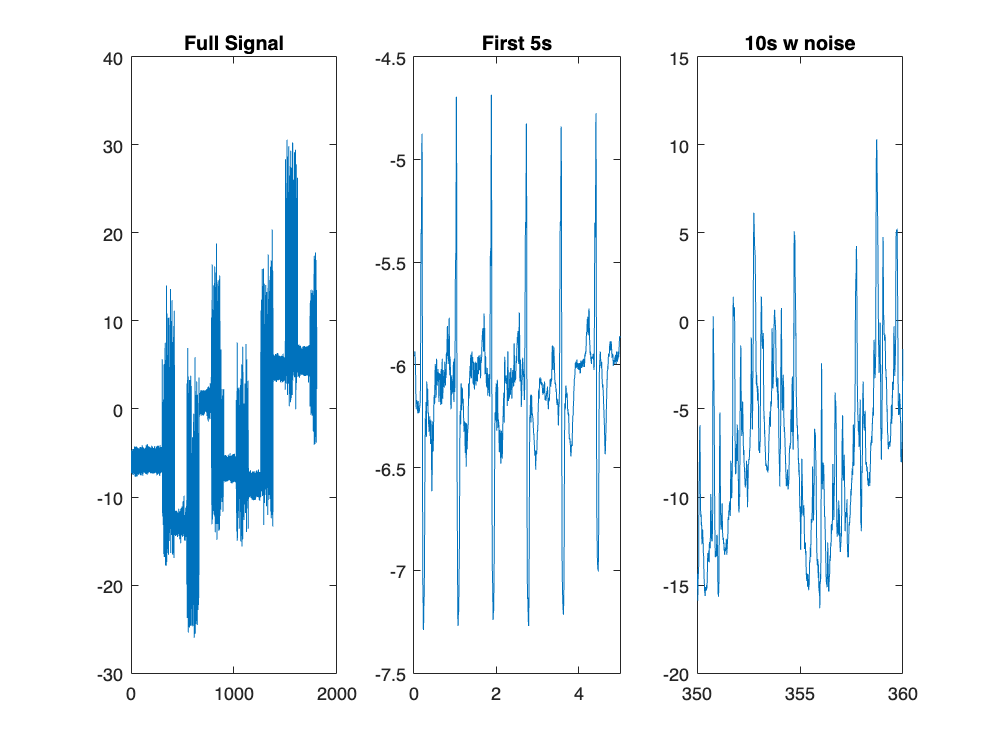

%Example Plot of 118e24
for i = 1:6
    figure; 
    subplot(1,3,1)
    plot(tm{i,1},ecg{i,1})
    title("Full Signal");
    subplot(1,3,2)
    plot(tm{i,1},ecg{i,1})
    xlim([0,5])
    title("First 5s");
    subplot(1,3,3)
    plot(tm{i,1},ecg{i,1})
    xlim([350,360])
    title("10s w noise");
end 

## First Attempt at PCA

file_idx = 4; 
data = ecg{file_idx,1};
n = length(data); 
fs = Fs(file_idx,1);
%Split into 10s segments
sec_per_seg = 1; 
segs = floor(n/(fs*sec_per_seg));
data = data(1:segs*fs*sec_per_seg); 
data_ar = reshape(data,[fs*sec_per_seg,segs]);
data_ar = data_ar';
coeffs = pca(data_ar);

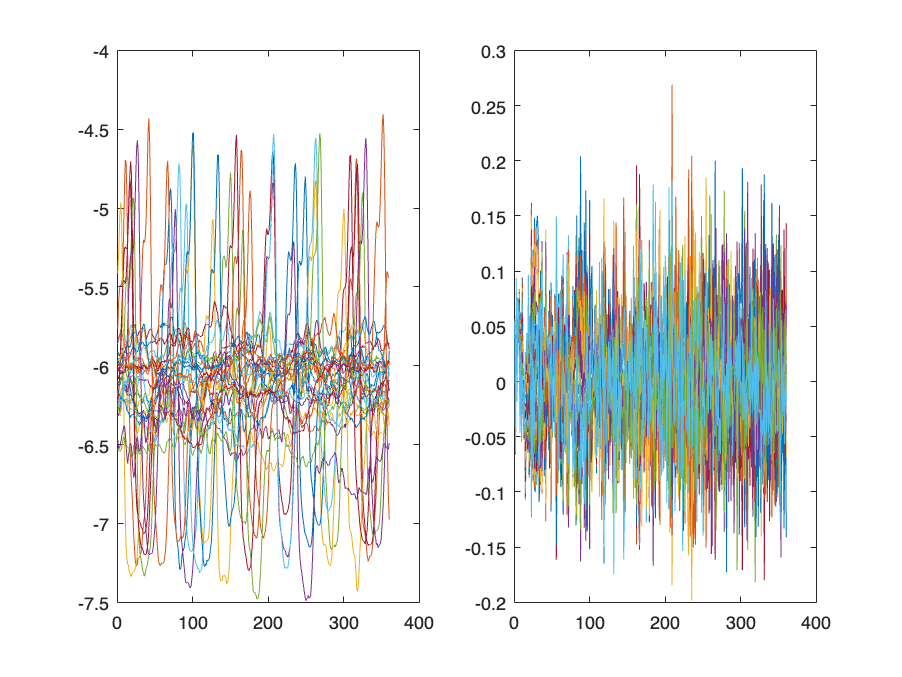


figure; 
subplot(1,2,1); 
plot(data_ar(1:30,:)'); 
subplot(1,2,2); 
plot(coeffs(1:20,:)'); 

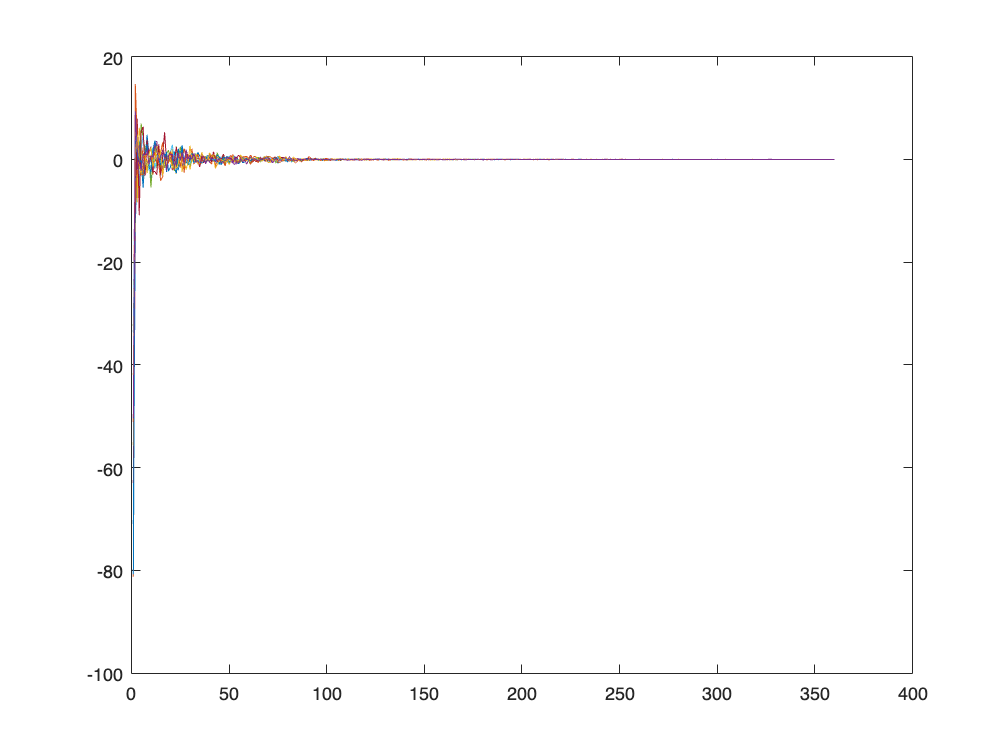

% Compute the PCA transformation.
signals = data_ar; 
[coeff, ~, ~, ~, explained] = pca(signals,"Algorithm","eig");

% Multiply the raw signals by the pca transformation matrix to get the PCA components
pca_timeseries = signals * coeff(:,:);
figure; 
plot(pca_timeseries(end-10:end,:)');

## Second Attempt at PCA

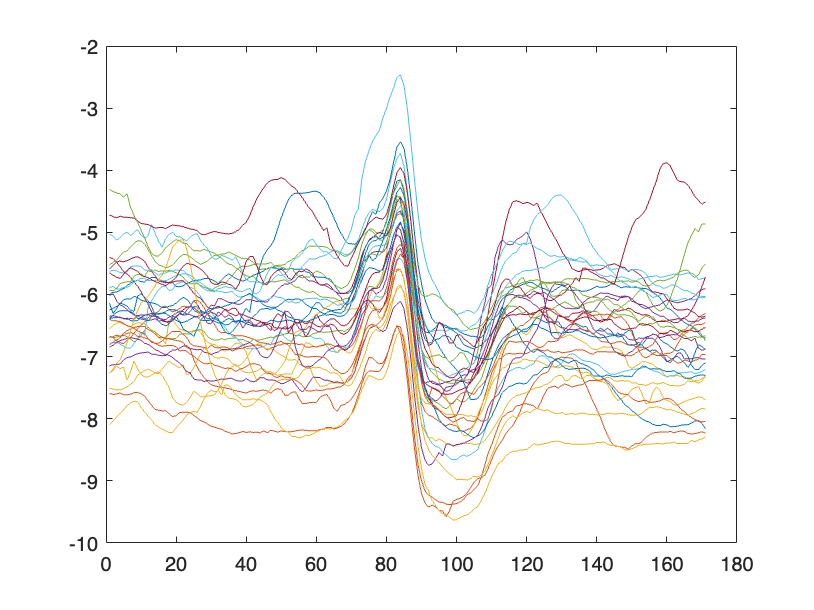

file_idx = 4; 
data = ecg{file_idx,1};
n = length(data); 
fs = Fs(file_idx,1);
this_rr = rr{file_idx,1};
this_tm = tm{file_idx,1};
%Split into segments by peaks
samp_per_seg = min(this_rr);
segs = length(this_rr); 
data_ar = [];
for i = 2:length(this_tm)
    t = this_tm(i);
    data_row = data(t-80:t+samp_per_seg-81)'; 
    data_ar = [data_ar; data_row];
end 
plot(data_ar(360:390,:)'); 

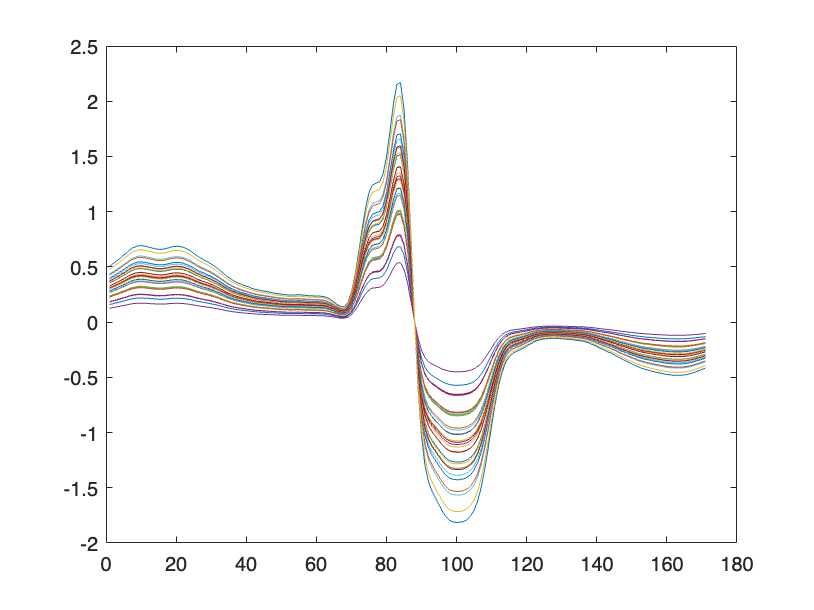

[coeff, score, latent, ~, explained] = pca(data_ar');
n = 1; % Example: Use the first 4 principal components
reconstructed_signal = score(:, 1:n) * coeff(:, 1:n)';
reconstructed_signal = reconstructed_signal';
plot(reconstructed_signal(360:390,:)');